## Wireless Networking Project (2026) -- Part 2

This is a continuation of the Documentation started in Part 1.

# Picking Up Where We Left Off

To continue, you will need to load the network we have previously designed.  To do this, create a new `WirelesssNetwork `object and then use the `Load` method:

net = WirelessNetwork;
net.Load
net

net =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


As a reminder, this is a network comprised of 28 cells in a hexagonal layout -- 7 clusters of 4 cells each.

# Showing the Network on an Actual Map

Now, let's show our network on an actual geographic map of the region we are designing our network for -- the city of Morgantown.  This can be accomplished by using the MapCity method

help WirelessNetwork.MapCity

  method MapCity shows a map of the city, with the base station locations overlaid
  and (optionally), the locations of the mobiles
 
  usage: Recording = obj.MapCity( [ms_locations], [pl_exponent] )
         Recording = a Matlab movie showing the locations of the mobiles
         [ms_locations] = mobile locations, in a vector or cell array
         [pl_exponent] = path loss exponent (optional argument)



For now, ignore the optional arguments (which are explained later) and run the method without arguments:

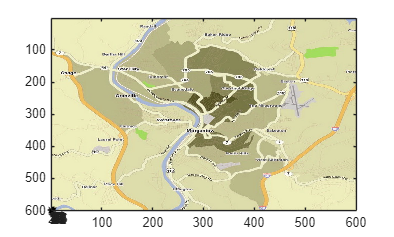

ans = struct with fields:
       cdata: [275×434×3 uint8]
    colormap: []


net.MapCity

The result is a map showing Morgantown along with the locations of the base stations.  Where are the base stations?  They are all located in the lower left of the figure, which is not where we want them to be.

The problem is that the map extends for 600 units in each direction starting at location (0,0) and extending in the north-east direction, whereas our network was only about 10 units in each direction and was centered at (0,0).   To fix this, we need to *scale* the network by stretching it out and recentering it on the map.

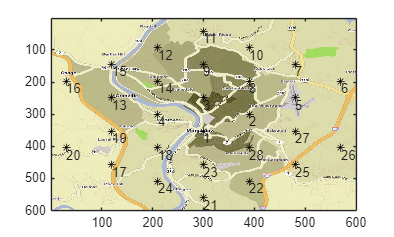

ans = struct with fields:
       cdata: [275×434×3 uint8]
    colormap: []


% move base stations to the 600 by 600 grid,
% so they are aligned with the mobile locations
bs_expanded = 60*net.bs_locations;
bs_shift = bs_expanded + 300 + 300*1i;
net.bs_locations = bs_shift;

% now map it again
net.MapCity

# Loading Mobile Location Data

Now let's load some data associated with the users of your network.  A file called `MobileLocationData` contains the locations of mobiles attempting to make a call each hour of a particular day.  We can load the file using matlab's `load` command:

load( 'MobileLocationData' )

The file contains two variabes: `call_attempts` and `ms_locations`.

The variable `call_attempts` is a vector containing the number of attempts each hour:

call_attempts 

call_attempts =          500         400         300         200         250         450         600         900        1250        1100        1100        1600        1700        1400        1350        1450        1750        1800        2000        1850        1600        1250        1000         750


The vector contains 24 values, one for each hour of the day starting at 1:00 military time (1 AM) and ending at 24:00 military time (12 AM).  The peak demand is at 19:00 (7 PM), where 2000 attempts are made. 

The locations of the mobiles making these calls are stored in `ms_locations`.  Because the number of calls varies from one hour to the next, the data cannot be stored in a standard matrix. Instead, it is stored in a *cell array*.  To access the locations for the 1st hour (as an example), use the following syntax:

ms_locations{1}

ans = 1.0e+02 *

   4.4126 + 0.6725i   3.7906 + 2.9132i   3.7349 + 1.5401i   1.0939 + 2.0285i   2.5050 + 3.6186i   3.6520 + 2.2073i   0.9854 + 1.9632i   3.8847 + 3.5802i   4.6367 + 3.3475i   2.2864 + 0.7228i   3.1433 + 2.8467i   2.0932 + 1.5402i   2.6689 + 1.5343i   1.3250 + 4.6398i   3.7761 + 4.5295i   3.9537 + 2.6420i   1.7655 + 3.7548i   3.3247 + 3.0824i   1.0528 + 2.2377i   2.5561 + 3.1063i   3.5100 + 3.5229i   3.2424 + 1.1760i   2.2617 + 5.3294i   4.0623 + 4.3700i   5.9298 + 4.9210i   3.6839 + 3.6964i   4.4037 + 3.0665i   2.6939 + 3.6770i   2.5715 + 2.1424i   4.6787 + 3.2532i   2.7883 + 3.7223i   2.9806 + 2.8687i   3.2746 + 0.9780i   4.3968 + 2.5072i   2.8342 + 4.6722i   3.6904 + 2.6093i   2.9258 + 2.9015i   1.9315 + 2.0694i   1.8479 + 1.2381i   2.0285 + 3.7313i   1.7586 + 4.8030i   3.8878 + 3.4324i   4.7787 + 2.5570i   2.1640 + 3.8397i   4.2714 + 5.0776i   1.3782 + 5.5721i   1.0321 + 2.7505i   3.5610 + 1.7949i   4.0847 + 2.0025i   2.8012 + 0.9460i


Note the use of curly brackets when accessing the cell array.  These are the locations of the mobiles that are attempting to make a call during the 1st hour.

The locations of the mobiles can be shown on the city map by providing them as the optional first argument:

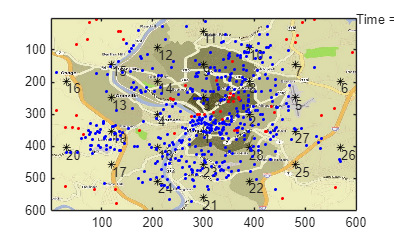

ans = struct with fields:
       cdata: [275×434×3 uint8]
    colormap: []


% show the mobiles at 1:00 AM on the city map
net.MapCity( ms_locations{1} )

A mobile is shown as a blue dot if its SINR at its location is above the threshold, and is red if it is below the threshold.  The argument can be an entire cell array, in which case it will create a *movie* that animates the location of the mobiles at each hour of the day:

To create a movie showing the mobiles each hour of the day, uncomment (i.e., remove the % character) and run the following line of code (it is commented out because it will take several seconds to run):

% Recording = net.MapCity( ms_locations );

To play the movie, uncomment the following line and the cut-and-paste it into your MATLAB command window (Live Editor won't play movies):

% movie( Recording, 1, 2 )

# Showing the Mobiles on the Coverage Map

In addition to showing the mobiles on the city map, it is useful to show the mobiles on the coverage map.  This can be done by using the `MapMobiles` method.  `MapMobiles` is similar to `MapCity`, but instead of overlaying the mobiles on the city map, it overlays the mobiles on the coverage map.

help WirelessNetwork.MapMobiles

  method MapMobiles shows the location of the mobiles
  and produces a movie
  
  usage: Recording obj.MapMobiles( ms_locations, [pl_exponent] )
         Recording = a Matlab movie showing the locations of the mobiles
         ms_locations = mobile locations, in a vector or cell array
         [pl_exponent] = path loss exponent (optional argument)



The calling syntax is like `MapCity`.  For instance, to show the mobiles at the 1st hour:

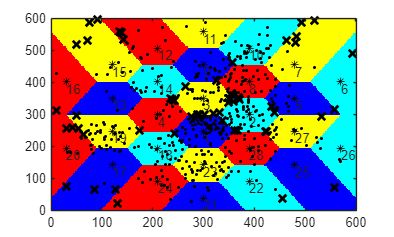

ans = struct with fields:
       cdata: [275×434×3 uint8]
    colormap: []


% show the mobiles at 1:00 AM on the coverage map
net.MapMobiles( ms_locations{1} )

This is useful in determining which cell a particular mobile is in.  Because the cell map is colored, mobiles above the threshold are indicated by black dots, while mobiles below the threshold are indicated by black x's. You can now identify the mobiles that have problems getting coverage.

To create a movie showing the mobiles each hour of the day overlaid on the coverage map, uncomment and run the following line of code:

% Recording = net.MapMobiles( ms_locations );

To play the movie, uncomment the following line and the cut-and-paste it into your MATLAB command window (since Live Editor won't play movies):

% movie( Recording, 1, 2 )

# Analyzing Performance

While the Coverage, SINR, and City maps are useful and provide some insight into how your network is behaving, a true quantitative analysis of the system requires some numbers -- key performance indicators (KPIs).  We will use two KPIs -- one will be the number of callers that have a SINR above the threshold, and the other will be the number of callers that are actually able to get connected to the network.  Here, by *caller*, we refer to a user that is attempting to make a call.

Coverage is quantified by the number of callers whose SINR is above the threshold. This can be found at each hour of the day by simply computing the SINR for each mobile making a call and comparing it against the threshold.

However, simply having a high enough SINR is not enough.   There also has to be a channel available for the caller to use.  If a cell is too crowded and doesn't have enough channels, then the user will not be able to get on the network no matter how high their SINR is.   

Thus, a caller can *connect* if two conditions are true: (1) Their SINR has to be above the threshold, *and* (2) There has to be an available *traffic* channel in their cell.  Here, we again distinguish traffic channels from RF channels -- an *RF* channel is a channel with a certain bandwidth that has been acquired by purchasing a license,  but each RF channel can be used to support several *traffic* channels thanks to multiple access (e.g., 5G NR uses orthogonal frequency division muliple access -- OFDMA).   The number of traffic channels per RF channel is specified by the property `ms_per_channel`, which has a default value of 10.  Thus, if a cell has 2 RF channels, it will have 20 traffic channels; i.e., it can support 20 users at a time.

The number of connected users at each hour of the day can therefore be found by first counting the number of users in each cell that have a sufficient SINR.  If there are enough traffic channels in the cell to support all those users, then they are all counted as being connected.  However, if there are more covered users in the cell than there are traffic channels, then the number of connected users is equal to the number of the traffic channels in the cell.

The number of *covered* users and the number of *connected* users can be found using the AnalyzeNetwork method.

help WirelessNetwork.AnalyzeNetwork

  method AnalyzeNetwork will determine the number of connected users and number over the threshold
  usage: [num_connected, num_over_thresh] = obj.AnalyzeNetwork( ms_locations, [pl_exponent] )
         num_connected = number of mobiles that are above the threshold AND can obtain a channel
         num_over_thresh = number of mobiles over the SINR threshold
         ms_locations = mobile locations, in a vector or cell array
         [pl_exponent] = path loss exponent (optional argument)



The argument `ms_locations` may be a vector containing the locations for a specific hour, or it may be a cell array containing the locations for all hours of the day.

[num_connected, num_over_thresh] = net.AnalyzeNetwork( ms_locations )

num_connected =    358   316   256   181   223   332   394   471   527   518   522   550   569   538   531   546   575   572   592   575   559   511   481   434


num_over_thresh =          445         367         268         181         223         415         551         811        1131         998        1003        1449        1543        1280        1223        1310        1591        1636        1816        1686        1451        1126         902         678


The output `num_over_thresh` is a vector that gives the number of mobiles at each hour that are above the SINR threshold (i.e., the number that are covered).  Idealy, we would like this value to be close to the number of call attempts.  We can plot the fraction of call attempts that are above the threshold as follows:

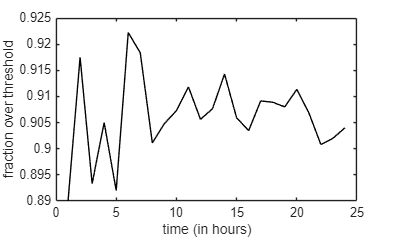

fraction_over_thresh = num_over_thresh./call_attempts;
plot( 1:length(call_attempts), fraction_over_thresh, '-k' );
xlabel( 'time (in hours)' );
ylabel( 'fraction over threshold' );

The output `num_connected` is the number of connected user.  As described above, a user is connected if it is both over the SINR threshold and is able to get a traffic channel. Since the user's SINR must also be above the threshold to connect, it follows that `num_connected` cannot be greater than `num_over_thresh`.

We can plot the total number of connected users, the number of call attempts, and the number over threshold on the same plot:

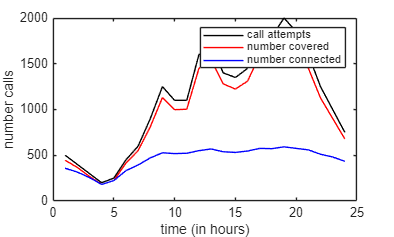

plot( 1:length(call_attempts), call_attempts, '-k', ...
    1:length(call_attempts), num_over_thresh, '-r', ...
    1:length(call_attempts), num_connected, '-b' );
xlabel( 'time (in hours)' );
ylabel( 'number calls' );
legend( 'call attempts', 'number covered', 'number connected' );

You may need to move the figure's legend so that it does not cover a curve.

Alternatively, we could plot the fraction of connected users (just like we plotted fraction of users over the threshold).

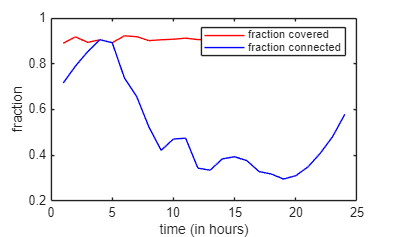

fraction_connected = num_connected./call_attempts;
plot( 1:length(call_attempts), fraction_over_thresh, '-r', ...
    1:length(call_attempts), fraction_connected, '-b');
xlabel( 'time (in hours)' );
ylabel( 'fraction' );
legend( 'fraction covered', 'fraction connected');

# Troubleshooting Performance

The best way to troubleshoot your network is to identify cells that are overloaded, i.e., they have more users attempting to make a call than can be supported by the traffic channels available in the cell, which is called the *capacity *of the cell (not to be confused with Shannon capacity).  The capacity of each cell is stored in the `max_users` property, 

net.max_users

ans =     30
    30
    20
    20
    30
    30
    20
    20
    30
    30
    20
    20
    30
    30
    20


The number of users above the threshold in each cell or sector can be found as an optional output argument for the `ComputeSINR` method.  For instance, at the busy hour (19:00), this is found using:

[SINR_dB, num_ms_per_sec] = net.ComputeSINR( ms_locations{19} ); 
num_ms_per_sec

num_ms_per_sec =    285
   143
   100
    38
    42
     4
    19
   116
    62
    84
    18
    43
    15
    61
    31


By comparing `num_ms_per_sec` against `net.max_users`, it is possible to identify overloaded cells (or sectors, if sectorization is used, see next section).  Cells that are overloaded can be dealt with by moving the location of base stations, changing base station transmit powers, or changing the channel set assignments.

Now that you are done with Part 2 of this tutorial, please proceed to Part 3 (WirelessProjectPart3.mlx).  There is no need to save your work, as we will pick up using the file created in Part 1.

Alternatively, you may now proceed to the file "WirelessProjectExample1.mlx", which is a complete example of a working project -- and then once done with that, move on to Part 3.